# Windkessel model

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES.

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter4/Windkessel'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

### The Windkessel model 

The Windkessel model is an interpretative model that allows us to achieve the following:

Given the aortic flow and the parameters of the model, we can generate aortic and peripheral pressure signals. 

Given the aortic flow and the aortic pressure, we can estimate the values of parameters such as arterial compliance that have physiological meaning and can be interpreted. 

The pressure  plays the role of the voltage at different points and the blood flow  of the current.

Parameters include:

- Z0 is the characteristic impedance of the artery

- R is the peripheral resistance 

- CA is the arterial compliance which is the change in arterial blood volume (due to a given change in arterial blood pressure, 

- L is the arterial inertance and it is defined as the change in pressure in the arterial segment versus the acceleration of the blood.

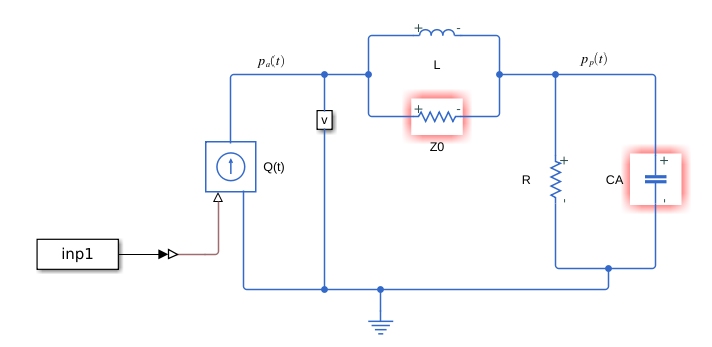

In this section Windkessel model will be presented. 

### Forward modeling

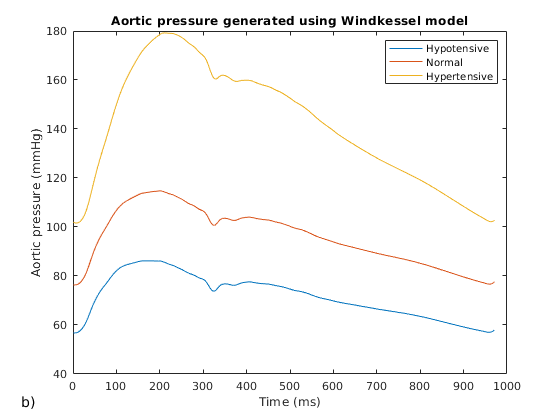

% Modeling Case 1

load('data_17s.mat')
a=[];
fs=200;
src1=zeros(200,0);
global start_pulse_ind;
global end_pulse_ind;
start_pulse_ind=15800;
end_pulse_ind=16841;
%src1=240*ones(65,1);
inp1(:,2)=TFP(:,2);  % flow
inp1(:,1)=TFP(:,1);
model_name = 'WK';
open_system(model_name)
param=[0.039 1.95 0.71 0.011; 0.043 1.5 0.95 0.015; 0.05 0.7 1.4 0.02];
%param=[3 2 0.6 0.005];
cases=['hypotensive', 'normotensive', 'hypertensive'];
figure
for level =1:3
   
    
    L = sdo.getParameterFromModel(model_name, 'L');
    L.Value=param(level,4);
    sdo.setValueInModel(model_name,L);
    
    Z0 = sdo.getParameterFromModel(model_name, 'Z0');
    Z0.Value=param(level,1);
    sdo.setValueInModel(model_name,Z0);
    
    R = sdo.getParameterFromModel(model_name, 'R');
    R.Value=param(level,3);
    sdo.setValueInModel(model_name,R);
    
    CA = sdo.getParameterFromModel(model_name, 'CA');
    CA.Value=param(level,2);
    sdo.setValueInModel(model_name,CA);
    
    % Collect these parameters into a vector.
    v = [L Z0 R CA];
    
    simOut = sim(model_name, 'CaptureErrors', 'on');
    %figure
    %plot(simOut.simout.Time, simOut.simout.Data)
    plot(simOut.simout.Data(14000:14970))
    hold on
end
xlabel("Time (ms)")
ylabel("Aortic pressure (mmHg)")
legend({'Hypotensive', 'Normal', 'Hypertensive'})
title("Aortic pressure generated using Windkessel model")
annonation_save('b)',"Fig4.4b.jpg", SAVE_FLAG);

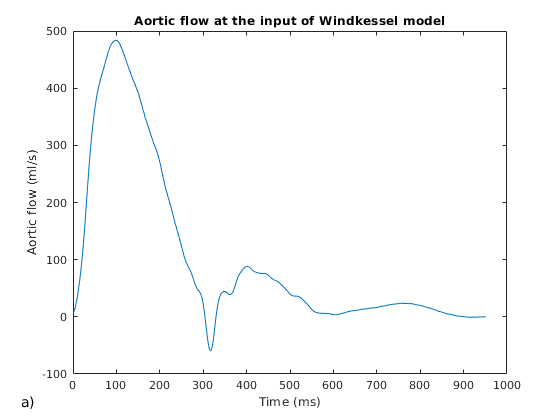


figure
plot(inp1(14000:14950,2))
xlabel("Time (ms)")
ylabel("Aortic flow (ml/s)")
title("Aortic flow at the input of Windkessel model")
annonation_save('a)',"Fig4.4a.jpg", SAVE_FLAG);


% hold on
% plot()

## Sensitivity analysis and fitting the model

In this section, we will load data that correspond to the flow and pressure of a hypotensive subject with low blood pressure. Then we will perform the following steps:

- Sensitivity analysis to determine the initial values of the parameters for the estimation 

- Selection of parameters that need to be optimized.

- Fitting the parameters of the model.

- Determining the accuracy of the fitting since we already know the parameters for the hypotensive subject. 

Sensitivity analysis

% Modeling Case 1 - hypotensive subject
% Sensitivity analysis
out(:,2)=TFP(:,3); % we can also ake the BP signal from the hypotensive subject above
out(:,1)=TFP(:,1);

[EvalResult, ParamValues, p] = sensitivityEvaluationWK(out)

ps =   ParameterSpace with properties:

            ParameterNames: {'Z0'  'CA'  'R'  'L'}
    ParameterDistributions: [1×4 prob.UniformDistribution]
           RankCorrelation: []
                   Options: [1×1 sdo.SampleOptions]
                     Notes: []


EvalResult = 100×1 table
    CustomReq
    _________

     406.29  
      15245  
       3574  
     1150.9  
     3115.6  
     7371.3  
     103.76  
     1245.9  
      16702  
     631.73  
     3401.2  
      14067  
     4137.9  
     4381.1  
     1982.5  
      12626  


ParamValues = 100×4 table
       Z0         CA          R           L     
    ________    _______    _______    __________

    0.036538     1.8888    0.51456     0.0089474
    0.048387      1.539     1.9386     0.0079182
    0.053251     2.2124    0.12442     0.0071158
     0.03965    0.92333    0.39621     0.0077394
    0.049616    0.70463    0.17107    0.00097271
     0.01243     2.1282     1.5687     0.0031098
    0.020558     2.0947    0.80747     0.0044961
    0.030858     0.8024     1.0483     0.0052895
    0.013547    0.58001     1.9814     0.0029549
    0.074551     1.3362    0.47133     0.0096582
    0.025569     1.5545     1.2854     0.0012468
    0.069632    0.58158     1.8808     0.0095514
    0.078088     1.7203     1.3466     0.0064016
    0.076541    0.50289     1.3375     0.0012601
    0.041768     2.1058     1.1491     0.0017829
    

 
p(1,1) =
 
       Name: 'Z0'
      Value: 0.0500
    Minimum: 0.0100
    Maximum: 0.1000
       Free: 1
      Scale: 0.0625
       Info: [1×1 struct]

 
p(2,1) =
 
       Name: 'CA'
      Value: 2
    Minimum: 0.5000
    Maximum: 3
       Free: 1
      Scale: 1
       Info: [1×1 struct]

 
p(3,1) =
 
       Name: 'R'
      Value: 0.6000
    Minimum: 0.1000
    Maximum: 2
       Free: 1
      Scale: 2
       Info: [1×1 struct]

 
p(4,1) =
 
       Name: 'L'
      Value: 0.0050
    Minimum: 5.0000e-04
    Maximum: 0.0100
       Free: 1
      Scale: 0.0312
       Info: [1×1 struct]

 
4x1 param.Continuous
 
lists of methods, superclasses
 


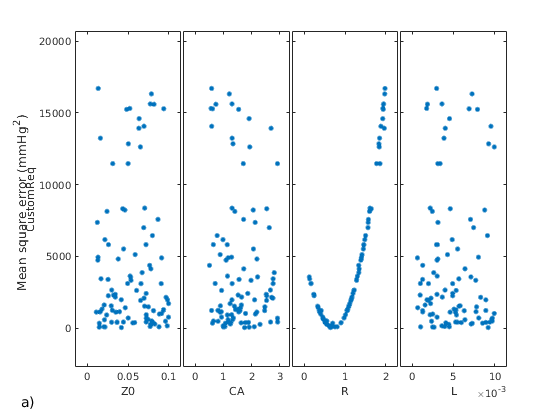


sdo.scatterPlot(ParamValues,EvalResult)
ylabel('Mean square error (mmHg^2)')
title("The scatter plot of mean square error vs. Windkessel parameters")

exportgraphics(gcf,"Fig4.5a.jpg", 'Resolution',600)
opts = sdo.AnalyzeOptions;
opts.Method = 'Correlation';
sensitivities = sdo.analyze(ParamValues,EvalResult, opts);
disp(sensitivities)

          CustomReq 
          __________

    Z0    -0.0040993
    CA      -0.11084
    R        0.81746
    L     -0.0018477



Selection of parameters

[fval, idx_min] = min(EvalResult.CustomReq);
L.Value = ParamValues.L(idx_min);
Z0.Value = ParamValues.Z0(idx_min);
R.Value = ParamValues.R(idx_min);
CA.Value = ParamValues.CA(idx_min);
L.Minimum=L.Value/2;
L.Maximum=L.Value*1.5;

Z0.Minimum=Z0.Value/2;
Z0.Maximum=Z0.Value*1.5;

R.Minimum=R.Value/2;
R.Maximum=R.Value*1.5;

CA.Minimum=CA.Value/2;
CA.Maximum=CA.Value*1.5;



Optimization

% Selection of parameters from the sensitivity analysis to be used in the
% optimization
Exp = sdo.Experiment(model_name);
v = [L Z0 R CA];
Exp = setEstimatedValues(Exp, v);   % use vector of parameters/states
Simulator = createSimulator(Exp);
% Simulator = sim(Simulator);
% % Retrieve logged signal data.
% SimLog = find(Simulator.LoggedData,get_param('WK','SignalLoggingName'));
% Sig_Log = find(SimLog,'Sig');


opts = sdo.OptimizeOptions;
opts.Method = 'fmincon';
estFcn = @(v) WK_OptEvalFcn(v, Simulator, Exp,out);
vOpt = sdo.optimize(estFcn, v, opts);


 Optimization started 14-Feb-2023 20:04:11

                               max                     First-order 
 Iter F-count        f(x)   constraint    Step-size    optimality
    0      9      46.7518            0
    1     21      26.3315            0        0.241     1.42e+03
    2     32      19.0406            0        0.411          863
    3     46       18.648            0        0.155          579
    4     53        10.82            0        0.569          340
    5     59        7.295            0        0.447          110
    6     70      4.43566            0        0.363          363
    7     78      2.69023            0        0.224         30.6
    8     86      1.11433            0         0.19         35.7
    9     94     0.657785            0       0.0668         7.39
   10    105     0.656918            0       0.0171         4.77
   11    113     0.653798            0      0.00317        0.756
   12    121     0.652268            0      0.00599         1.84
  

disp(vOpt)

 
(1,1) =
 
       Name: 'L'
      Value: 0.0138
    Minimum: 0.0046
    Maximum: 0.0138
       Free: 1
      Scale: 0.0156
       Info: [1×1 struct]

 
(1,2) =
 
       Name: 'Z0'
      Value: 0.0386
    Minimum: 0.0209
    Maximum: 0.0628
       Free: 1
      Scale: 0.0625
       Info: [1×1 struct]

 
(1,3) =
 
       Name: 'R'
      Value: 0.7127
    Minimum: 0.3234
    Maximum: 0.9702
       Free: 1
      Scale: 1
       Info: [1×1 struct]

 
(1,4) =
 
       Name: 'CA'
      Value: 2.0364
    Minimum: 0.8742
    Maximum: 2.6226
       Free: 1
      Scale: 2
       Info: [1×1 struct]

 
1x4 param.Continuous
 
lists of methods, superclasses
 


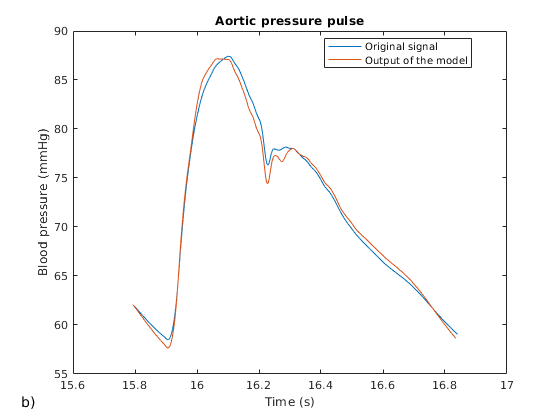



%% Visualizing Result of Optimization
%
% Obtain the model response after estimation.  Search for the
% model_residual signal in the logged simulation data.
Exp = setEstimatedValues(Exp, vOpt);   % use vector of parameters/states
Simulator = createSimulator(Exp);
Simulator = sim(Simulator);

figure
plot(out(start_pulse_ind:end_pulse_ind,1), out(start_pulse_ind:end_pulse_ind,2))
hold on
plot(Simulator.LoggedData.simout.Time(start_pulse_ind:end_pulse_ind), Simulator.LoggedData.simout.Data(start_pulse_ind:end_pulse_ind))
xlabel('Time (s)');
ylabel('Blood pressure (mmHg)');
legend({'Original signal', 'Output of the model'},'Location','Best')
title("Aortic pressure pulse")
annonation_save('b)',"Fig4.5b.jpg", SAVE_FLAG);

function Vals = WK_OptEvalFcn(v,Simulator,Exp,out)
%WK_EVALFCN
%
% Function called at each iteration of the evaluation problem.
%
% The function is called with a set of parameter values, P, and returns
% the evaluated cost, Vals.
%
% See the sdoExampleCostFunction function and sdo.evaluate for a more
% detailed description of the function signature.
%

%% Model Evaluation
%start_pulse_ind=15800;
%end_pulse_ind=16841;
global start_pulse_ind;
global end_pulse_ind;
% Simulate the model.
Exp = setEstimatedValues(Exp, v);   % use vector of parameters/states
Simulator = createSimulator(Exp,Simulator);
Simulator = sim(Simulator);

% Retrieve logged signal data.
% SimLog = find(Simulator.LoggedData,get_param('WK','SignalLoggingName'));
% Sig_Log = find(SimLog,'PaSig');
PaSig=Simulator.LoggedData.simout.Data;
% Evaluate the design requirements.
Vals.F = mean((PaSig(start_pulse_ind:end_pulse_ind)-out(start_pulse_ind:end_pulse_ind,2)).^2);
end
